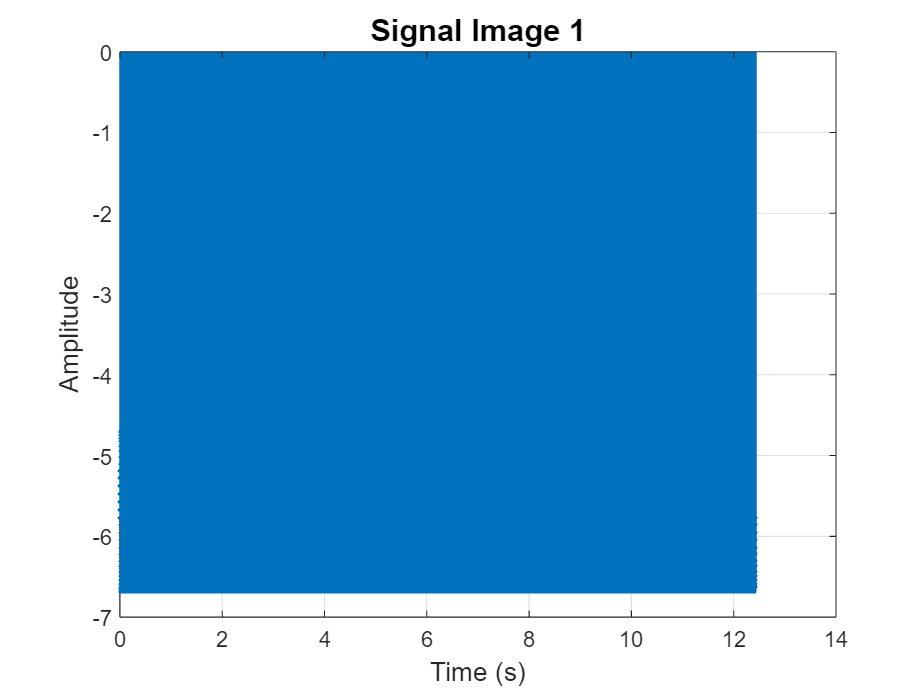

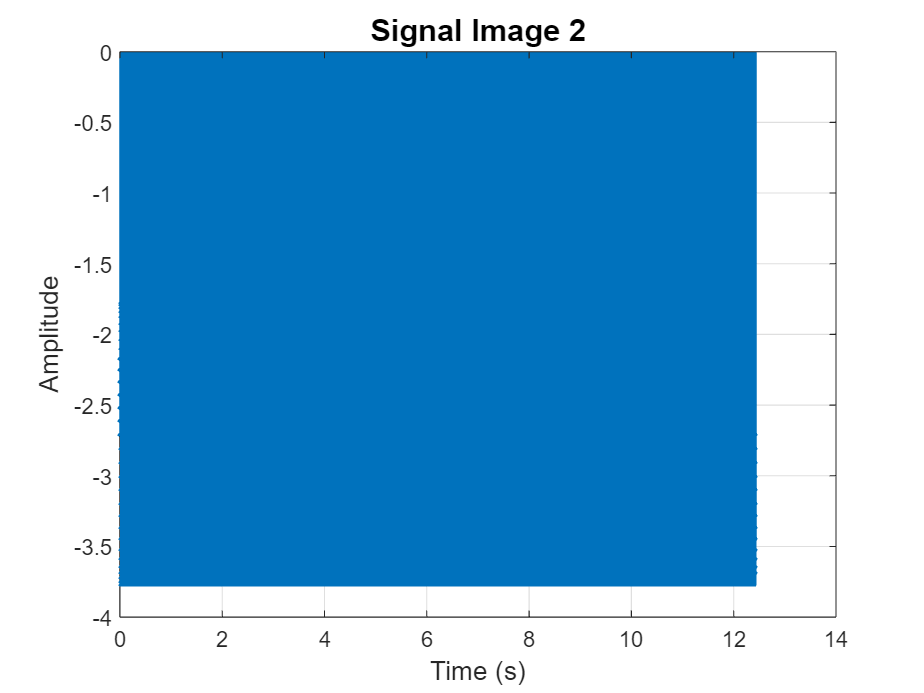

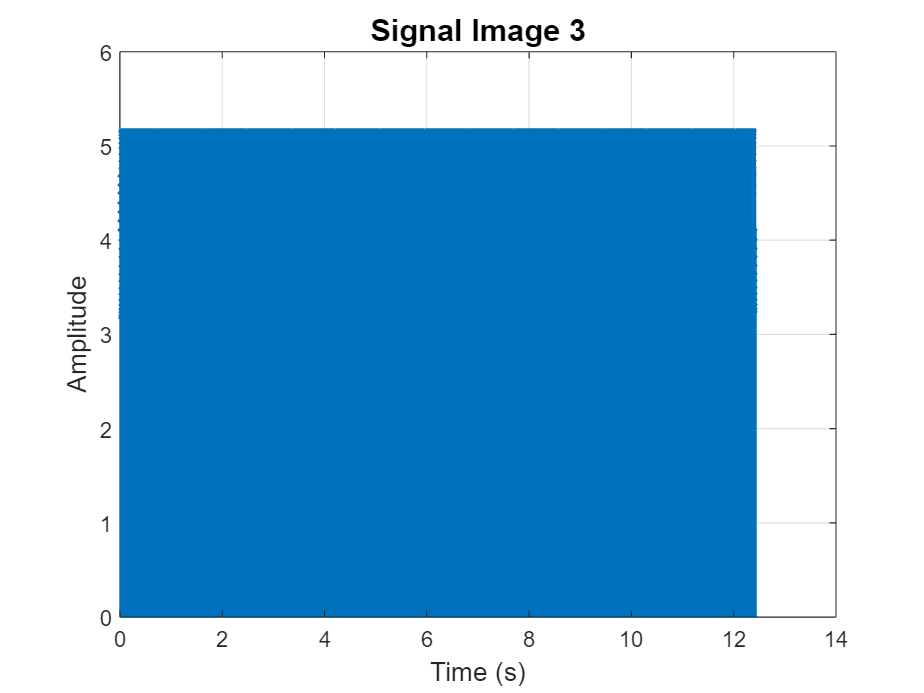

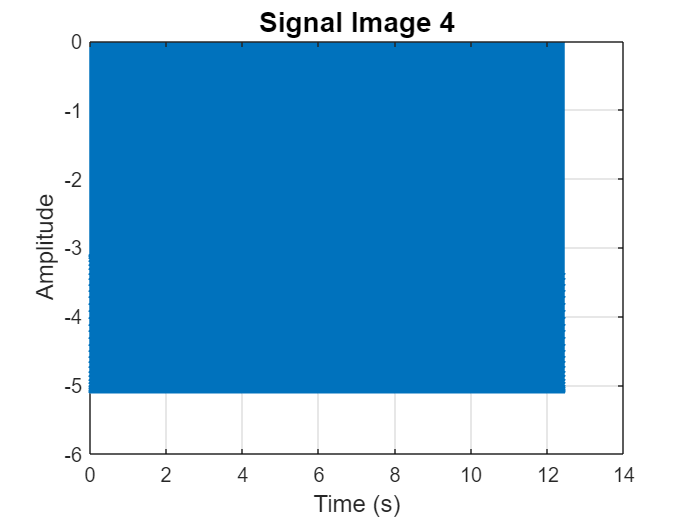

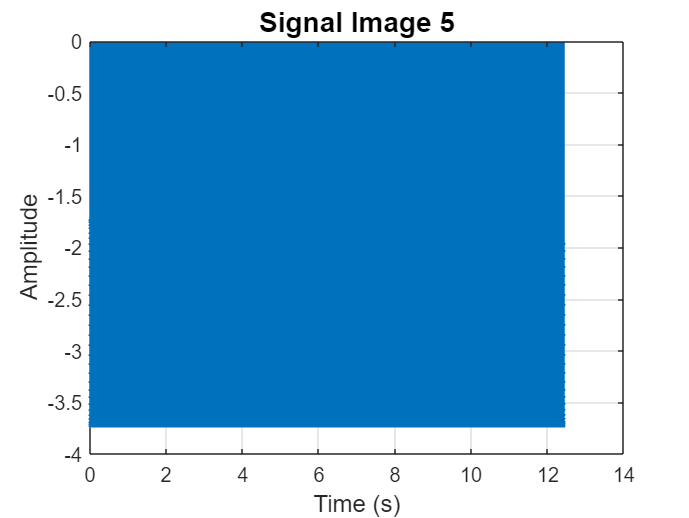

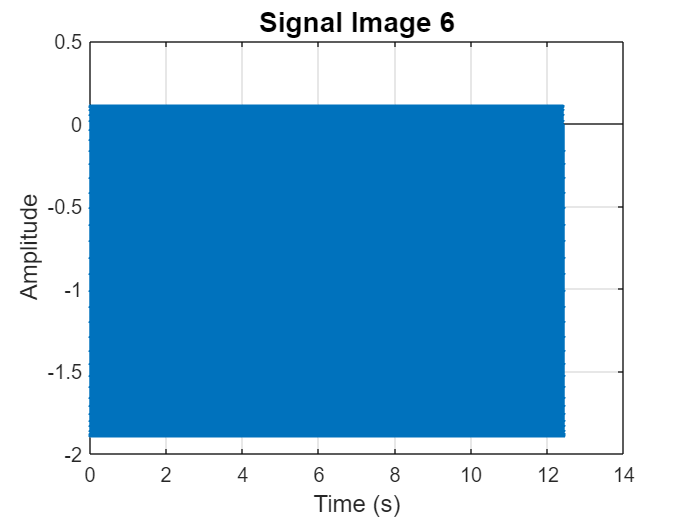

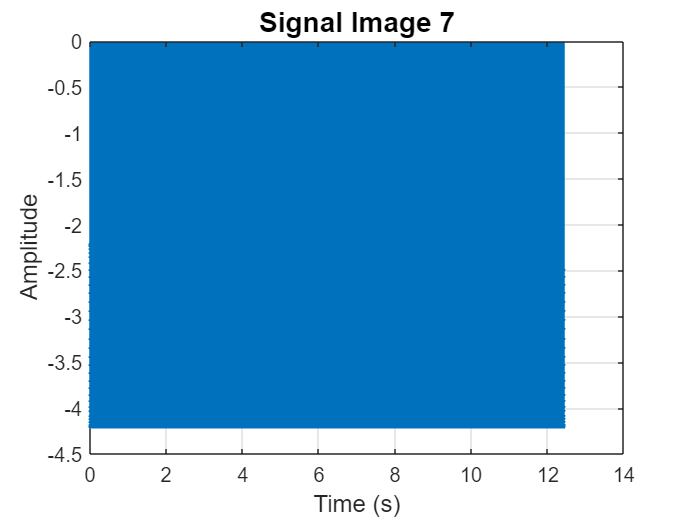

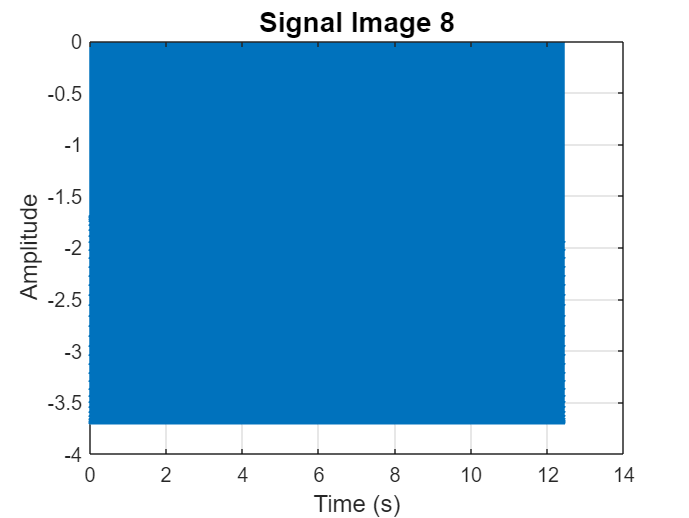

% Parameters
A = 1;                   % Amplitude
f = 50;                  % Frequency in Hz
sampling_rate = 3200;    % Sampling rate in Hz
num_cycles = 622;        % Number of cycles considered

% Time vector
T = 1 / f;                                       % Period of one cycle
duration = num_cycles * T;                       % Total duration of the signal
num_samples = duration * sampling_rate + 1;      % Number of samples
t = linspace(0, duration, num_samples);          % Time vector

% Angular frequency of the sinusoidal signal
omega = 2 * pi * f;
num_signals = 50;

% Generate 50 signal images
for signal_index = 1:num_signals
    % Define parameters with more randomness
    phi = 0.05 + 0.05 * randn();    % Random phi in [0.05, 0.1]
    theta = randn() * pi;           % Random theta with normal distribution
    
    % Calculate the signal
    signal = (1 + phi * sin(omega * t)) .* sin(omega * t) - theta;
    
    % Plot the signal as a stem plot with improved legibility
    figure;
    stem(t, signal, 'MarkerSize', 1, 'LineWidth', 0.5);
    xlabel('Time (s)', 'FontSize', 12);
    ylabel('Amplitude', 'FontSize', 12);
    title(['Signal Image ', num2str(signal_index)], 'FontSize', 14);
    grid on;
end